%%% Parameters for the motor simulink model

clear all;
close all;

% Actuator Gain calcuation

V = [0.25 0.5 0.75];
i_monitor = [0.23 0.47 0.72];
i_probe = [0.233 0.464 0.701];
i_avg = (i_monitor + i_probe) / 2;
K_a = mean(i_avg ./ V);

% Motor Properties
K_t = 4.24e-2; % Nm/A
J = 8.5e-6; %Kg-m^2
b = 3.7e-6; % Nm-s damping constant
T_friction = 8.05e-3; % Nm
% T_friction  = 0;

CPR = 500; % encoder resolution
delta_theta = 2*pi / (4 * CPR); % quantization level theta-m
Tau_filter = 0.05;

% loading criteria
T_load = 0;
time_load = 1; % s

command = 1; % rad

%plant
G_s = tf([K_t*K_a],[J,b,0]);


K = 0.41567;
z1 = 0.2739;
p1 = 0.1;
z2 = 0.5498;
p2 = 55.05;
C = K*tf([1 z1],[1 p1])*tf([1 z2],[1 p2])

C =
 
                     
  0.4157 s^2         
                     
          + 0.3424 s 
                     
             + 0.0626
                     
  -------------------
                     
  s^2 + 55.15 s      
                     
              + 5.505
                     
 
Continuous-time transfer function.



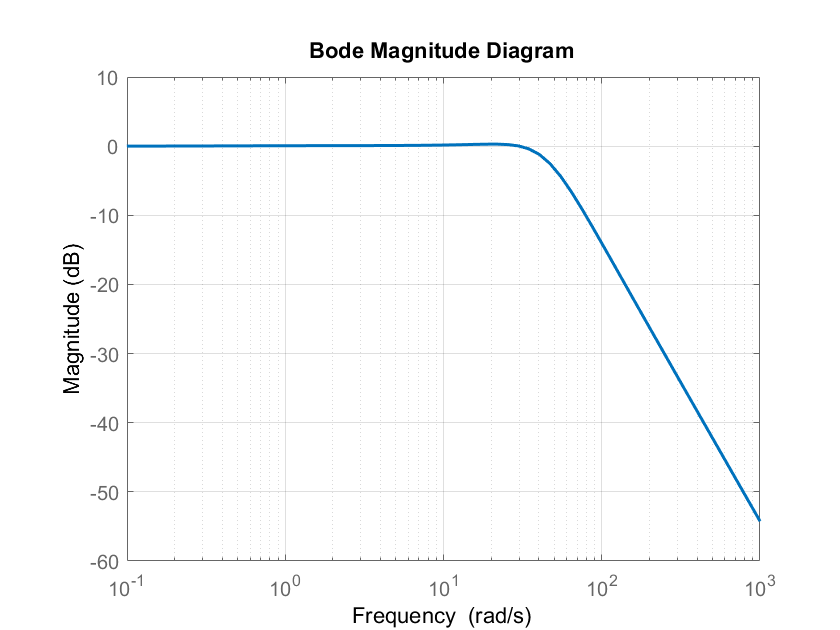



L_cl = feedback(C*G_s,1);
figure(1); box on;
h = bodeplot(L_cl);
title('Bode Magnitude Diagram');
set(findall(gcf,'type','line'),'linewidth',1.5)
setoptions(h,'PhaseVisible','off');
grid on;

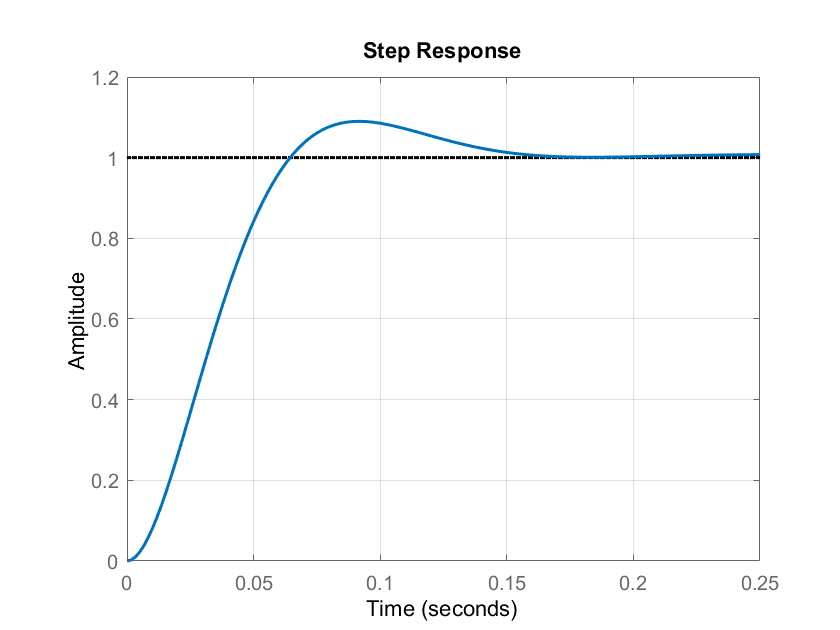


figure(2); box on;
step(L_cl)
set(findall(gcf,'type','line'),'linewidth',1.5);
grid on;

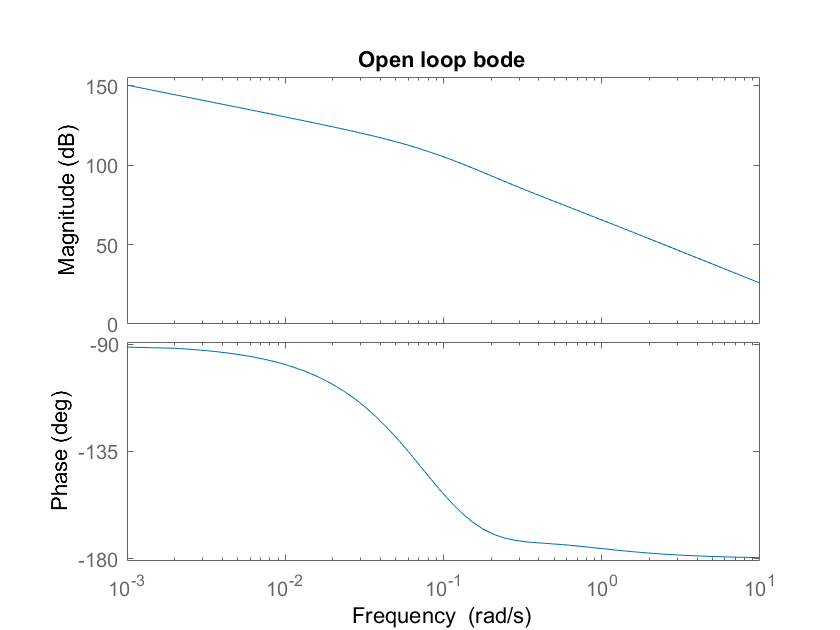



figure(2)
bode(C*G_s);
title('Open loop bode');

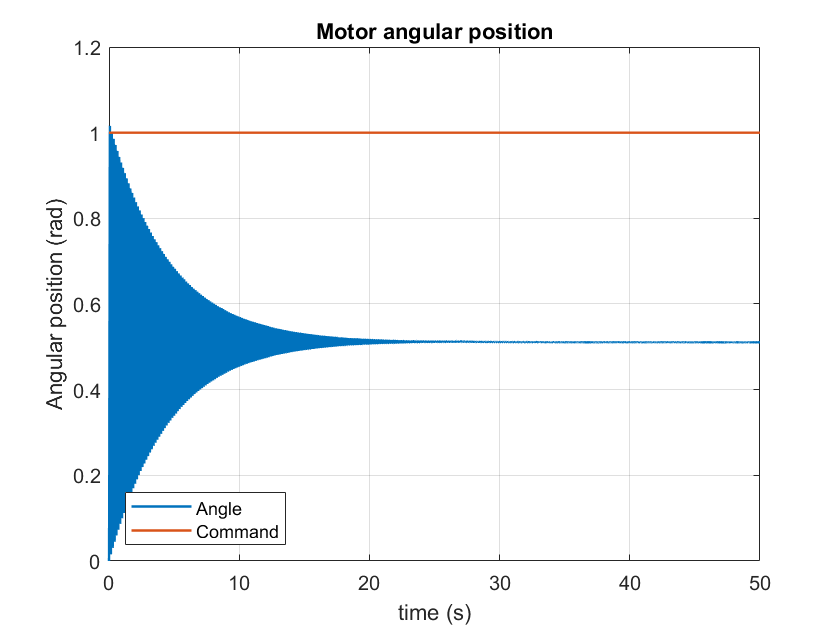


%% running simulink

sim('CL_Motor_model_position_control',50)

%%
figure(3)
clf
% plot speed vs time
plot(tout,position, 'LineWidth', 1.2)
hold on;
plot(tout, Theta_measured./Theta_measured, 'LineWidth', 1.2)
xlabel('time (s)');
ylabel('Angular position (rad)');
title('Motor angular position');
grid on
% xlim([2,4])
set(gca, 'fontsize', 10)
legend('Angle','Command', 'Location', 'southwest')

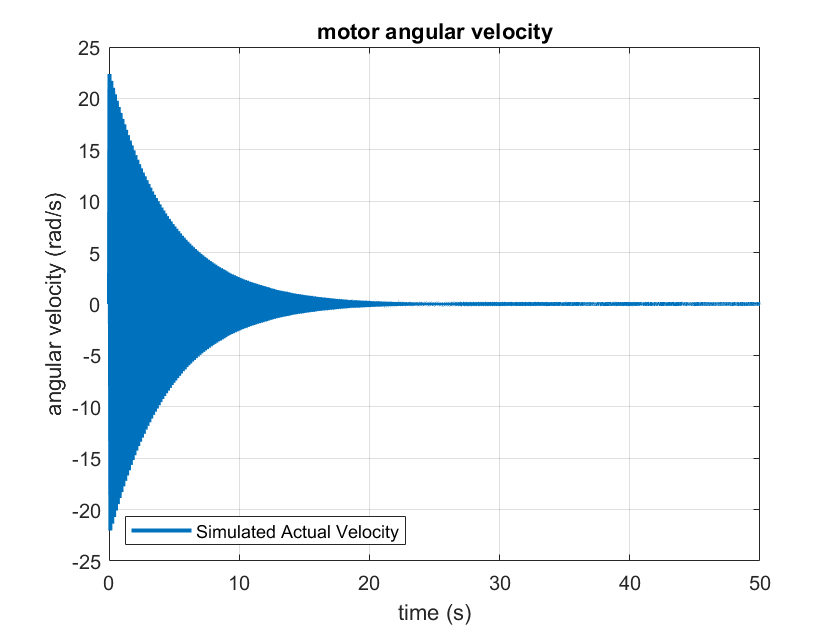



figure(4)
% plot theta vs time
plot(tout, speed, 'LineWidth', 2)
hold on

xlabel('time (s)');
ylabel('angular velocity (rad/s)');
title('motor angular velocity');
grid on
legend('Simulated Actual Velocity', 'Location', 'southwest')

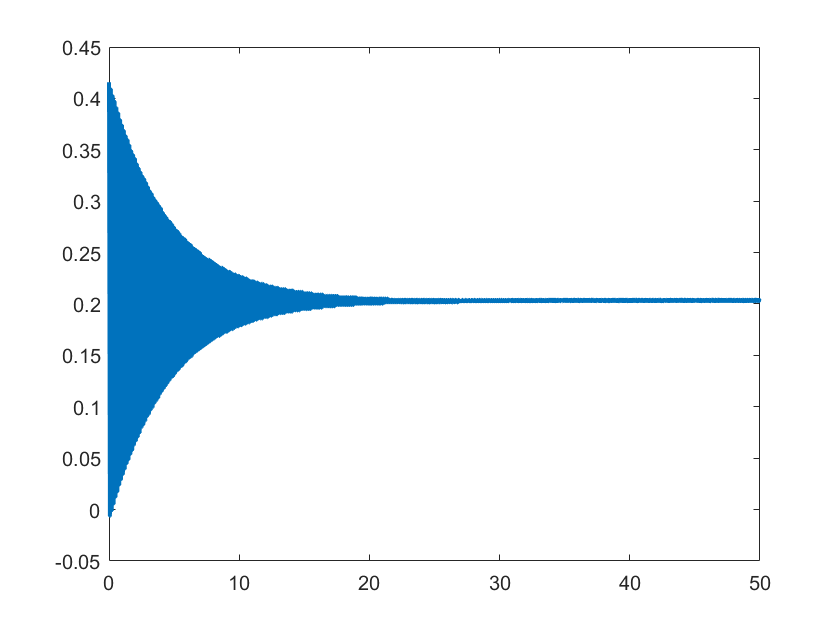


figure(5)
plot(tout, voltage, 'LineWidth', 2)